# Effect of different carbon source on methane (ch4) production of Methanosarcina(iGM746)

% load Methanosarcina barkeri str. Fusaro
% initCobraToolbox

% load model
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


model.lb(findRxnIDs(model,{'EX_meoh(e)'}))= -5;
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;

FBAsolution = optimizeCbModel(model);

**Methanol**

BIOMASS(1) = FBAsolution.v(model.c~=0)

BIOMASS = 0.0173

methaneProduction(1) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}))

methaneProduction = 3.4043

### Which metabolites can be exchanged?

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)
% Name = model.metNames(findMetIDs(model,regexprep(erase(exchangeReactions,"EX_"), '\(e\)', '[c]')));
lowerBound = model.lb(exchange_rxnID);
upperBound = model.ub(exchange_rxnID);
Flux = FBAsolution.v(exchange_rxnID);
T = table(exchangeReactions,lowerBound, upperBound, Flux);
sortrows(T,'Flux')

ans = 75×4 table
    exchangeReactions    lowerBound    upperBound       Flux    
    _________________    __________    __________    ___________

    {'EX_meoh(e)'   }         -5          1000                -5
    {'EX_nh4(e)'    }      -1000          1000          -0.18855
    {'EX_pi(e)'     }      -1000          1000         -0.015527
    {'EX_cys_L(e)'  }      -1000          1000         -0.010807
    {'EX_4abz(e)'   }      -1000          1000       -0.00041011
    {'EX_cobalt2(e)'}      -1000          1000       -8.1335e-05
    {'EX_nac(e)'    }      -1000          1000       -4.8442e-05
    {'EX_ni2(e)'    }      -1000          1000       -3.4601e-05
    {'EX_4hphac(e)' }          0          1000                 0
    {'EX_ac(e)'     }          0          1000                 0
    {'EX_actn_R(e)' }          0          1000                 0
 

### Which metabolites can be used as carbon source for Methanosarcina

For *Methanosarcina barkeri*, which is a methanogenic archaeon, several compounds can serve as carbon sources to support its growth and methane production. Methanosarcina species are known to utilize various substrates for methanogenesis, particularly one-carbon (C1) compounds, such as methylated amines and alcohols, as well as acetate. Here's a breakdown of what can be used as carbon sources from your list:

**Can be used as a carbon source:**

- **Trimethylamine** – A C1 compound, commonly used by methanogens for methane production.

- **Acetate** – A well-known substrate for *Methanosarcina barkeri*, used in the acetoclastic pathway for methane production.

- **Methanol** – A C1 compound often used by methanogens.

- **Methylamine** – Another methylated amine that can be utilized for methane production.

- **Dimethylamine** – Similar to trimethylamine and methylamine, this can also serve as a substrate for methanogenesis.

- **Methanethiol (CH4S)** – This sulfur-containing C1 compound can also serve as a carbon source for certain methanogens, including *Methanosarcina*.

- **Carbon monoxide (CO)** – *Methanosarcina* can potentially use CO as a substrate for methane production, though not as commonly as acetate or methylated compounds.

- **CO2 (carbon dioxide)** – Methanogens utilize CO2 in hydrogenotrophic methanogenesis when paired with hydrogen as an electron donor.

- **Ethanolamine** – Can potentially be used, as some methanogens are capable of using ethanolamine for methane production.

**Cannot be used as a carbon source:**

The following compounds either do not serve as carbon sources or have other metabolic functions:

- **Sulfate, Phosphate, Sulfur, Sulfite, Thiosulfate** – These are inorganic compounds primarily involved in sulfur or other metabolic cycles, not carbon sources.

- **Thiamin, (R)-Pantothenate, Riboflavin, Biotin, Cobinamide, etc.** – These are vitamins and cofactors, important for enzyme function, but not carbon sources.

- **Urea (CH4N2O)** – Urea can be used for nitrogen metabolism, but not typically as a carbon source.

- **L-Proline, L-Valine, L-Alanine, L-Glutamate, Glycine, L-Isoleucine, L-Leucine, L-Lysine** – These amino acids are not typically used as carbon sources by *Methanosarcina barkeri*.

- **Citrate, D-Gluconate, Glycerol, Glycine betaine** – While some bacteria utilize these compounds as carbon sources, they are not typically used by *Methanosarcina barkeri* for methane production.

**Trimethylamine**

clc
clearvars -except BIOMASS methaneProduction
% load('iGM746.mat')
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_tma(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
BIOMASS(2) = FBAsolution.v(model.c~=0)

BIOMASS =     0.0173    0.0663


methaneProduction(2) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}))

methaneProduction =     3.4043    9.9220


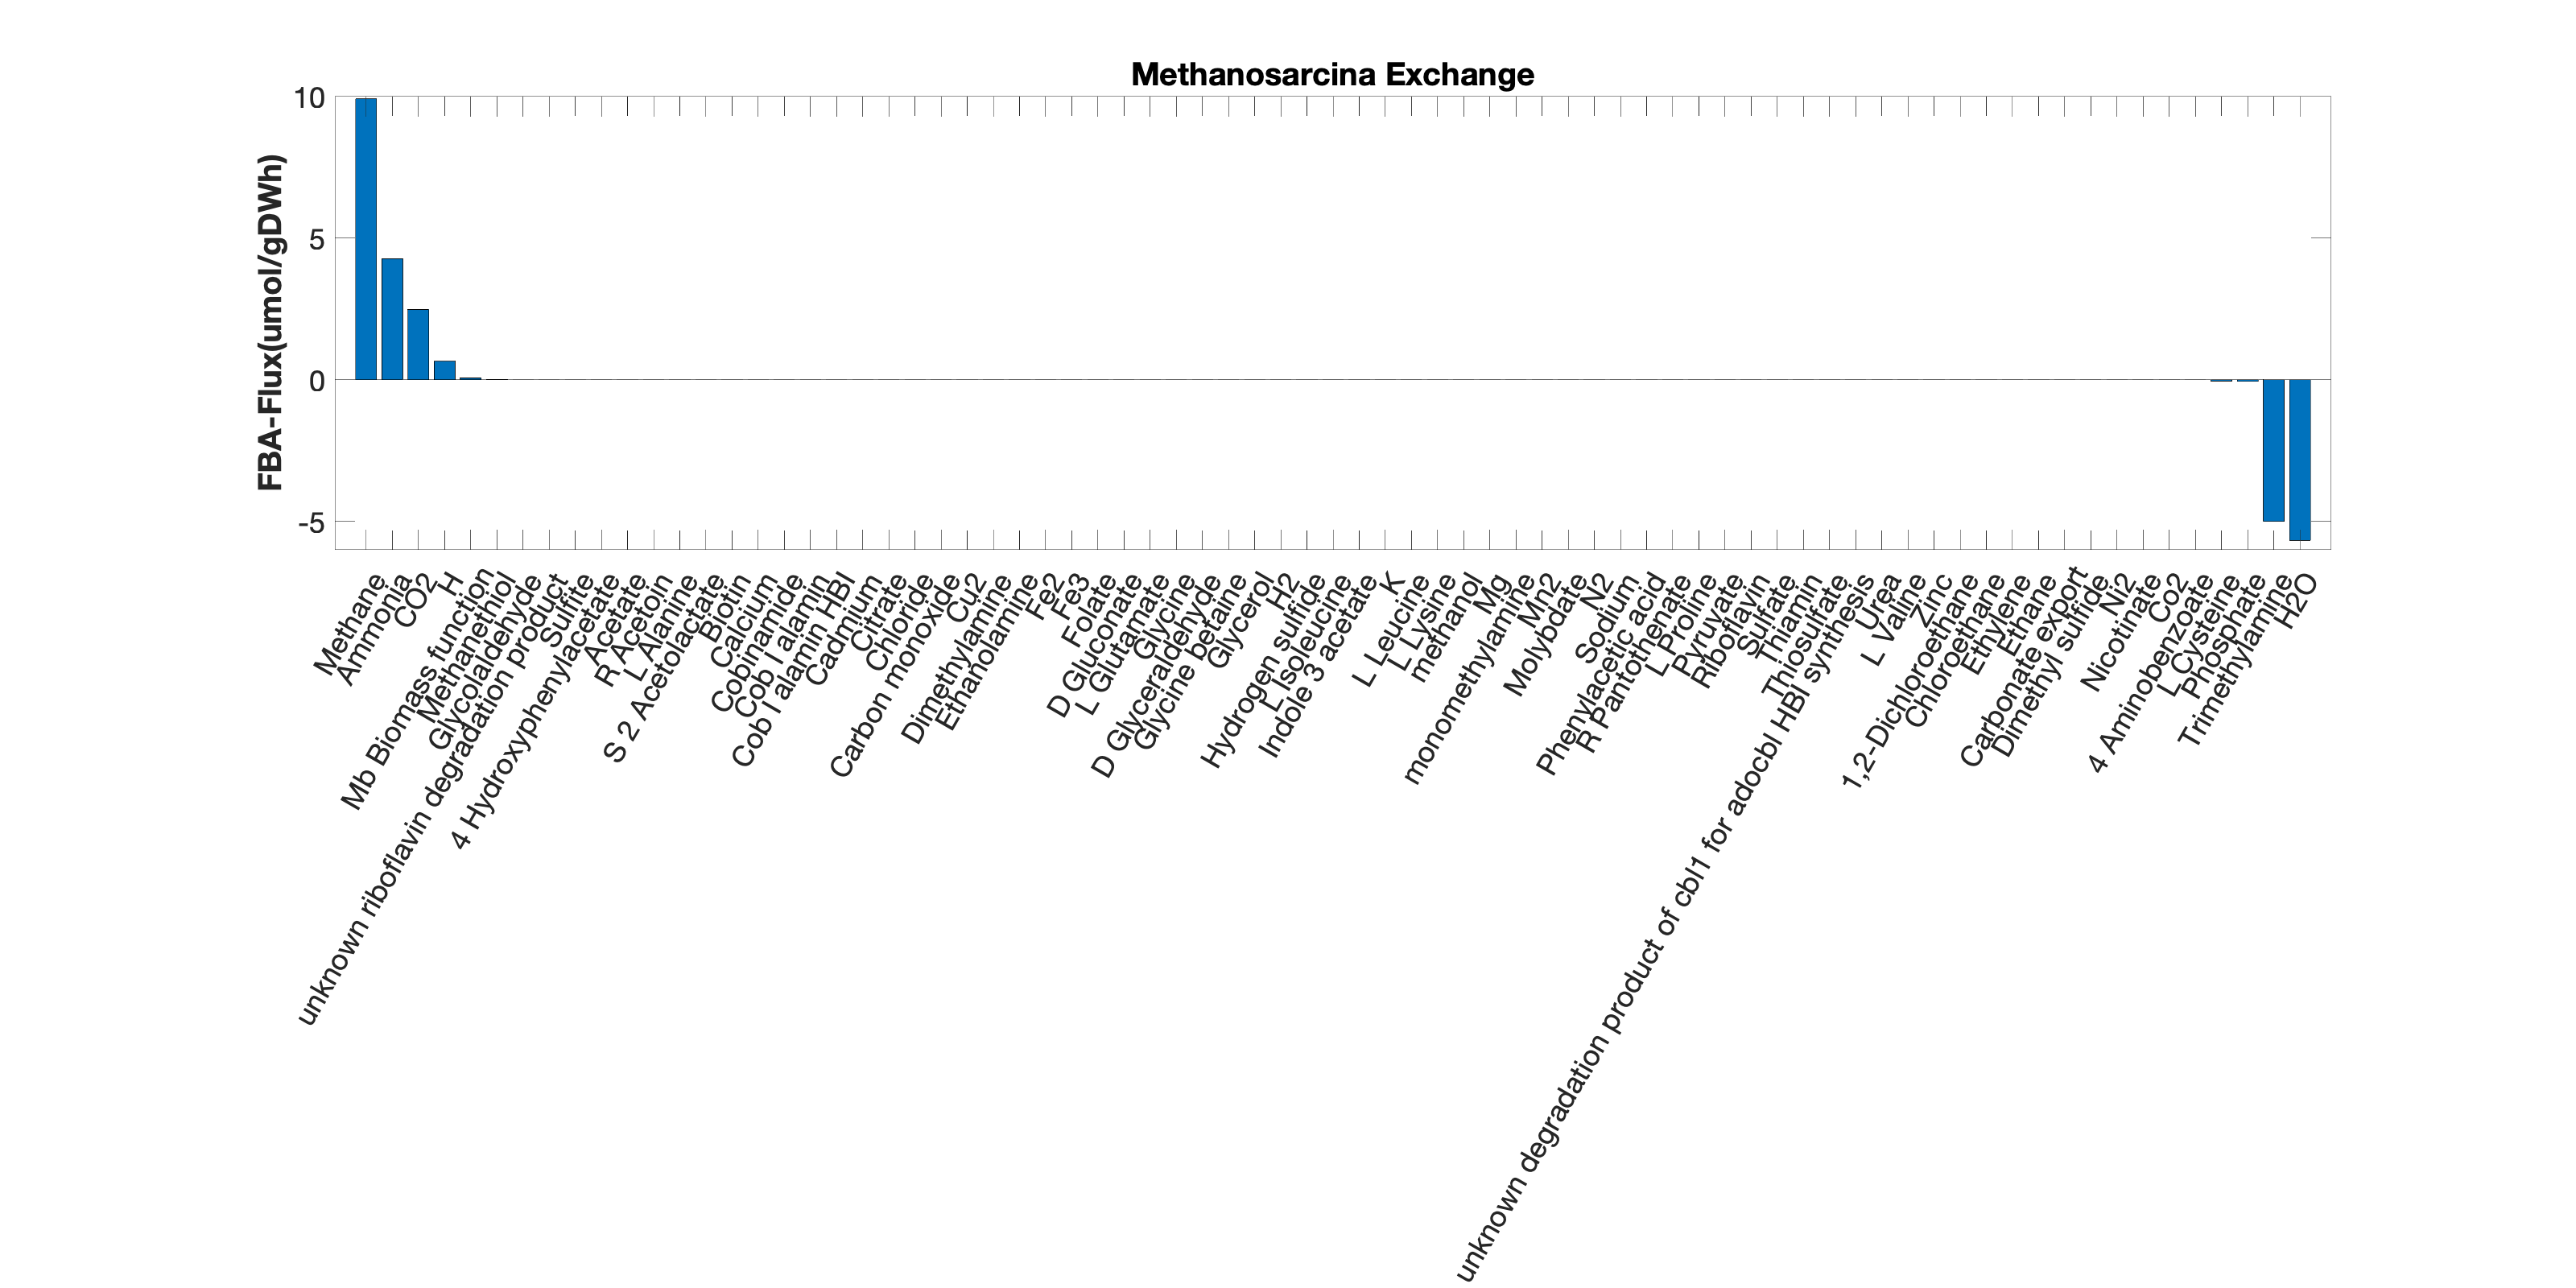

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"LPAREN e RPAREN");
c = erase(c,"exchange");

% c(find(contains(c,'_')))='-';

sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',18)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',14,'FontWeight','bold')
title(['Methanosarcina ',char(exchangeSubSystems)],'FontSize',18);

**Acetate**

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_meoh(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
BIOMASS(3) = FBAsolution.v(model.c~=0)

BIOMASS =     0.0173    0.0663    0.0130


methaneProduction(3) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}))

methaneProduction =     3.4043    9.9220    4.7401


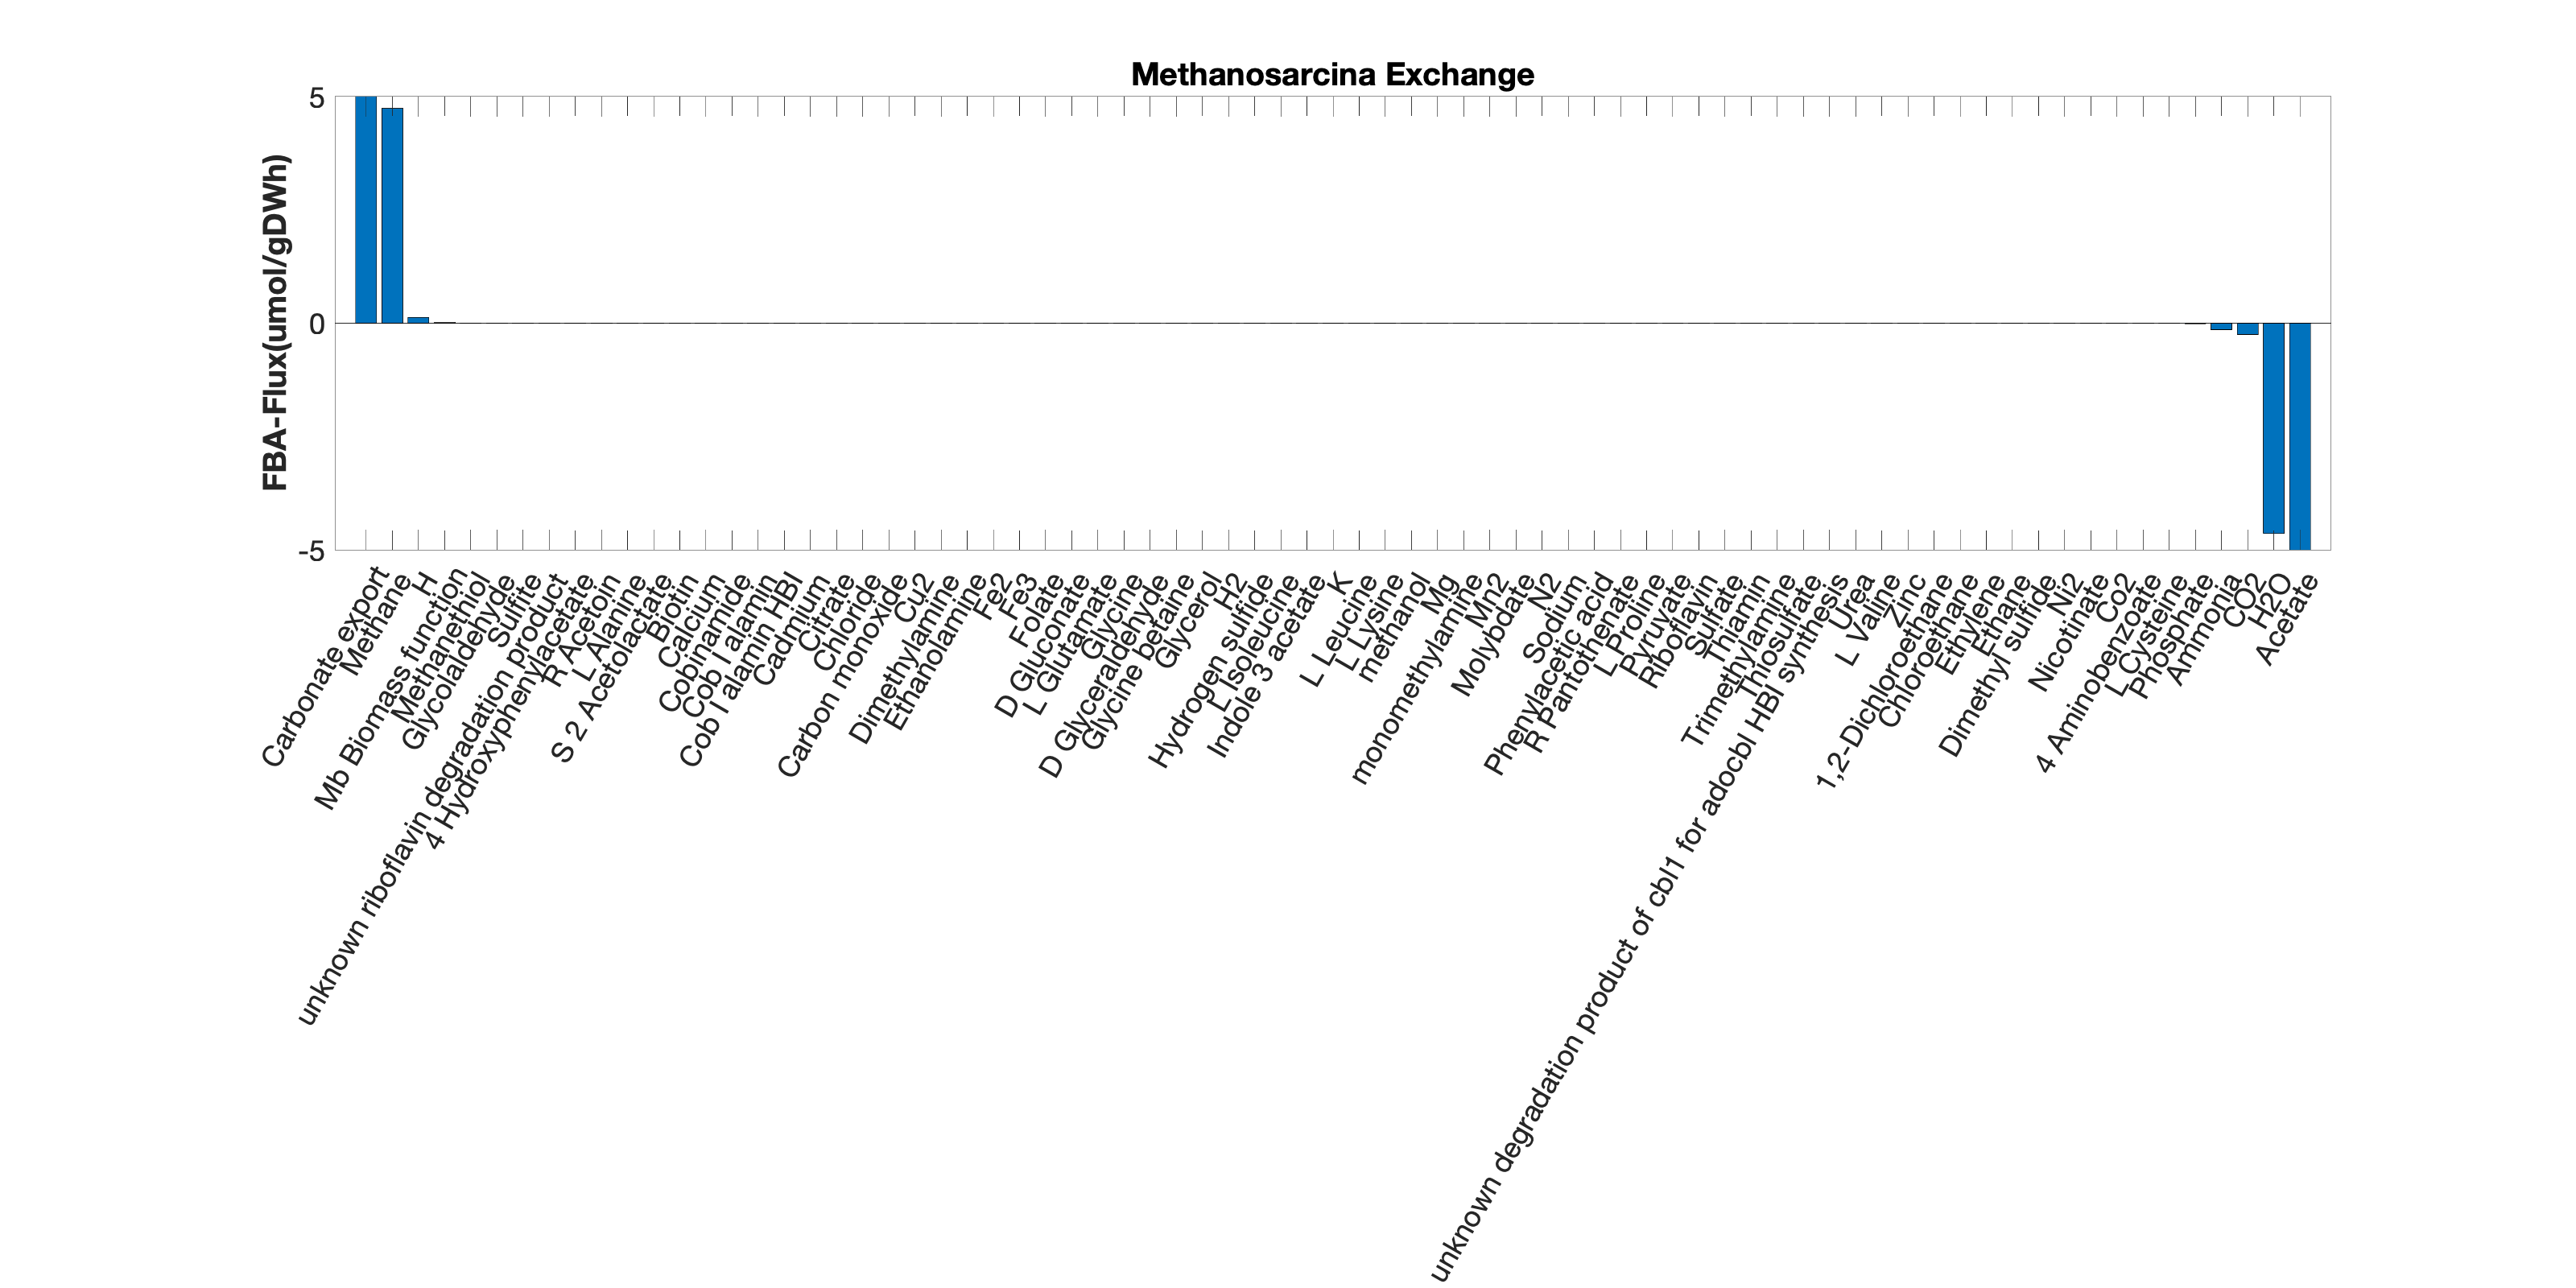

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"LPAREN e RPAREN");
c = erase(c,"exchange");

% c(find(contains(c,'_')))='-';

sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',18)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',14,'FontWeight','bold')
title(['Methanosarcina ',char(exchangeSubSystems)],'FontSize',18);

## **TEST r THEORY**

clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


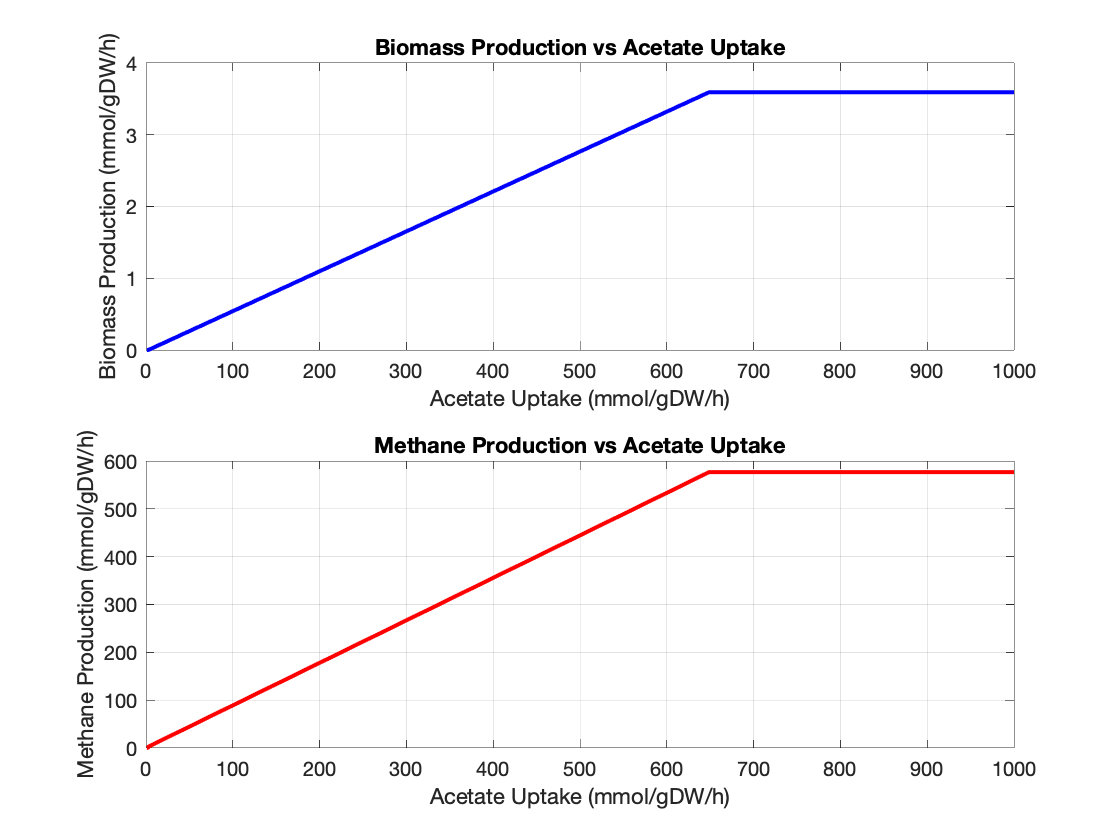

%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
for i = 1:1000
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= -(i);
FBAsolution= optimizeCbModel(model);
    if FBAsolution.stat == 1
        biomass(i) = FBAsolution.v(model.c~=0);
        MethaneProduction(i) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}));
    else
       biomass(i) = 0;
       MethaneProduction(i) = 0;
    end

end
% Define acetate uptake as the x-axis values
acetateUptake = 1 * (1:1000);  % As per your original code

% Plot biomass as a function of acetate uptake
figure;
subplot(2, 1, 1);  % Create a 2-row plot, biomass on top
plot(acetateUptake, biomass, 'b', 'LineWidth', 2);  % Blue line for biomass
xlabel('Acetate Uptake (mmol/gDW/h)');
ylabel('Biomass Production (mmol/gDW/h)');
title('Biomass Production vs Acetate Uptake');
grid on;

% Plot methane production as a function of acetate uptake
subplot(2, 1, 2);  % Methane production on bottom
plot(acetateUptake, MethaneProduction, 'r', 'LineWidth', 2);  % Red line for methane production
xlabel('Acetate Uptake (mmol/gDW/h)');
ylabel('Methane Production (mmol/gDW/h)');
title('Methane Production vs Acetate Uptake');
grid on;

**Methylamine**

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_mma(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
BIOMASS(4) = FBAsolution.v(model.c~=0)

BIOMASS =     0.0173    0.0663    0.0130    0.0060


methaneProduction(4) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}))

methaneProduction =     3.4043    9.9220    4.7401    3.6294


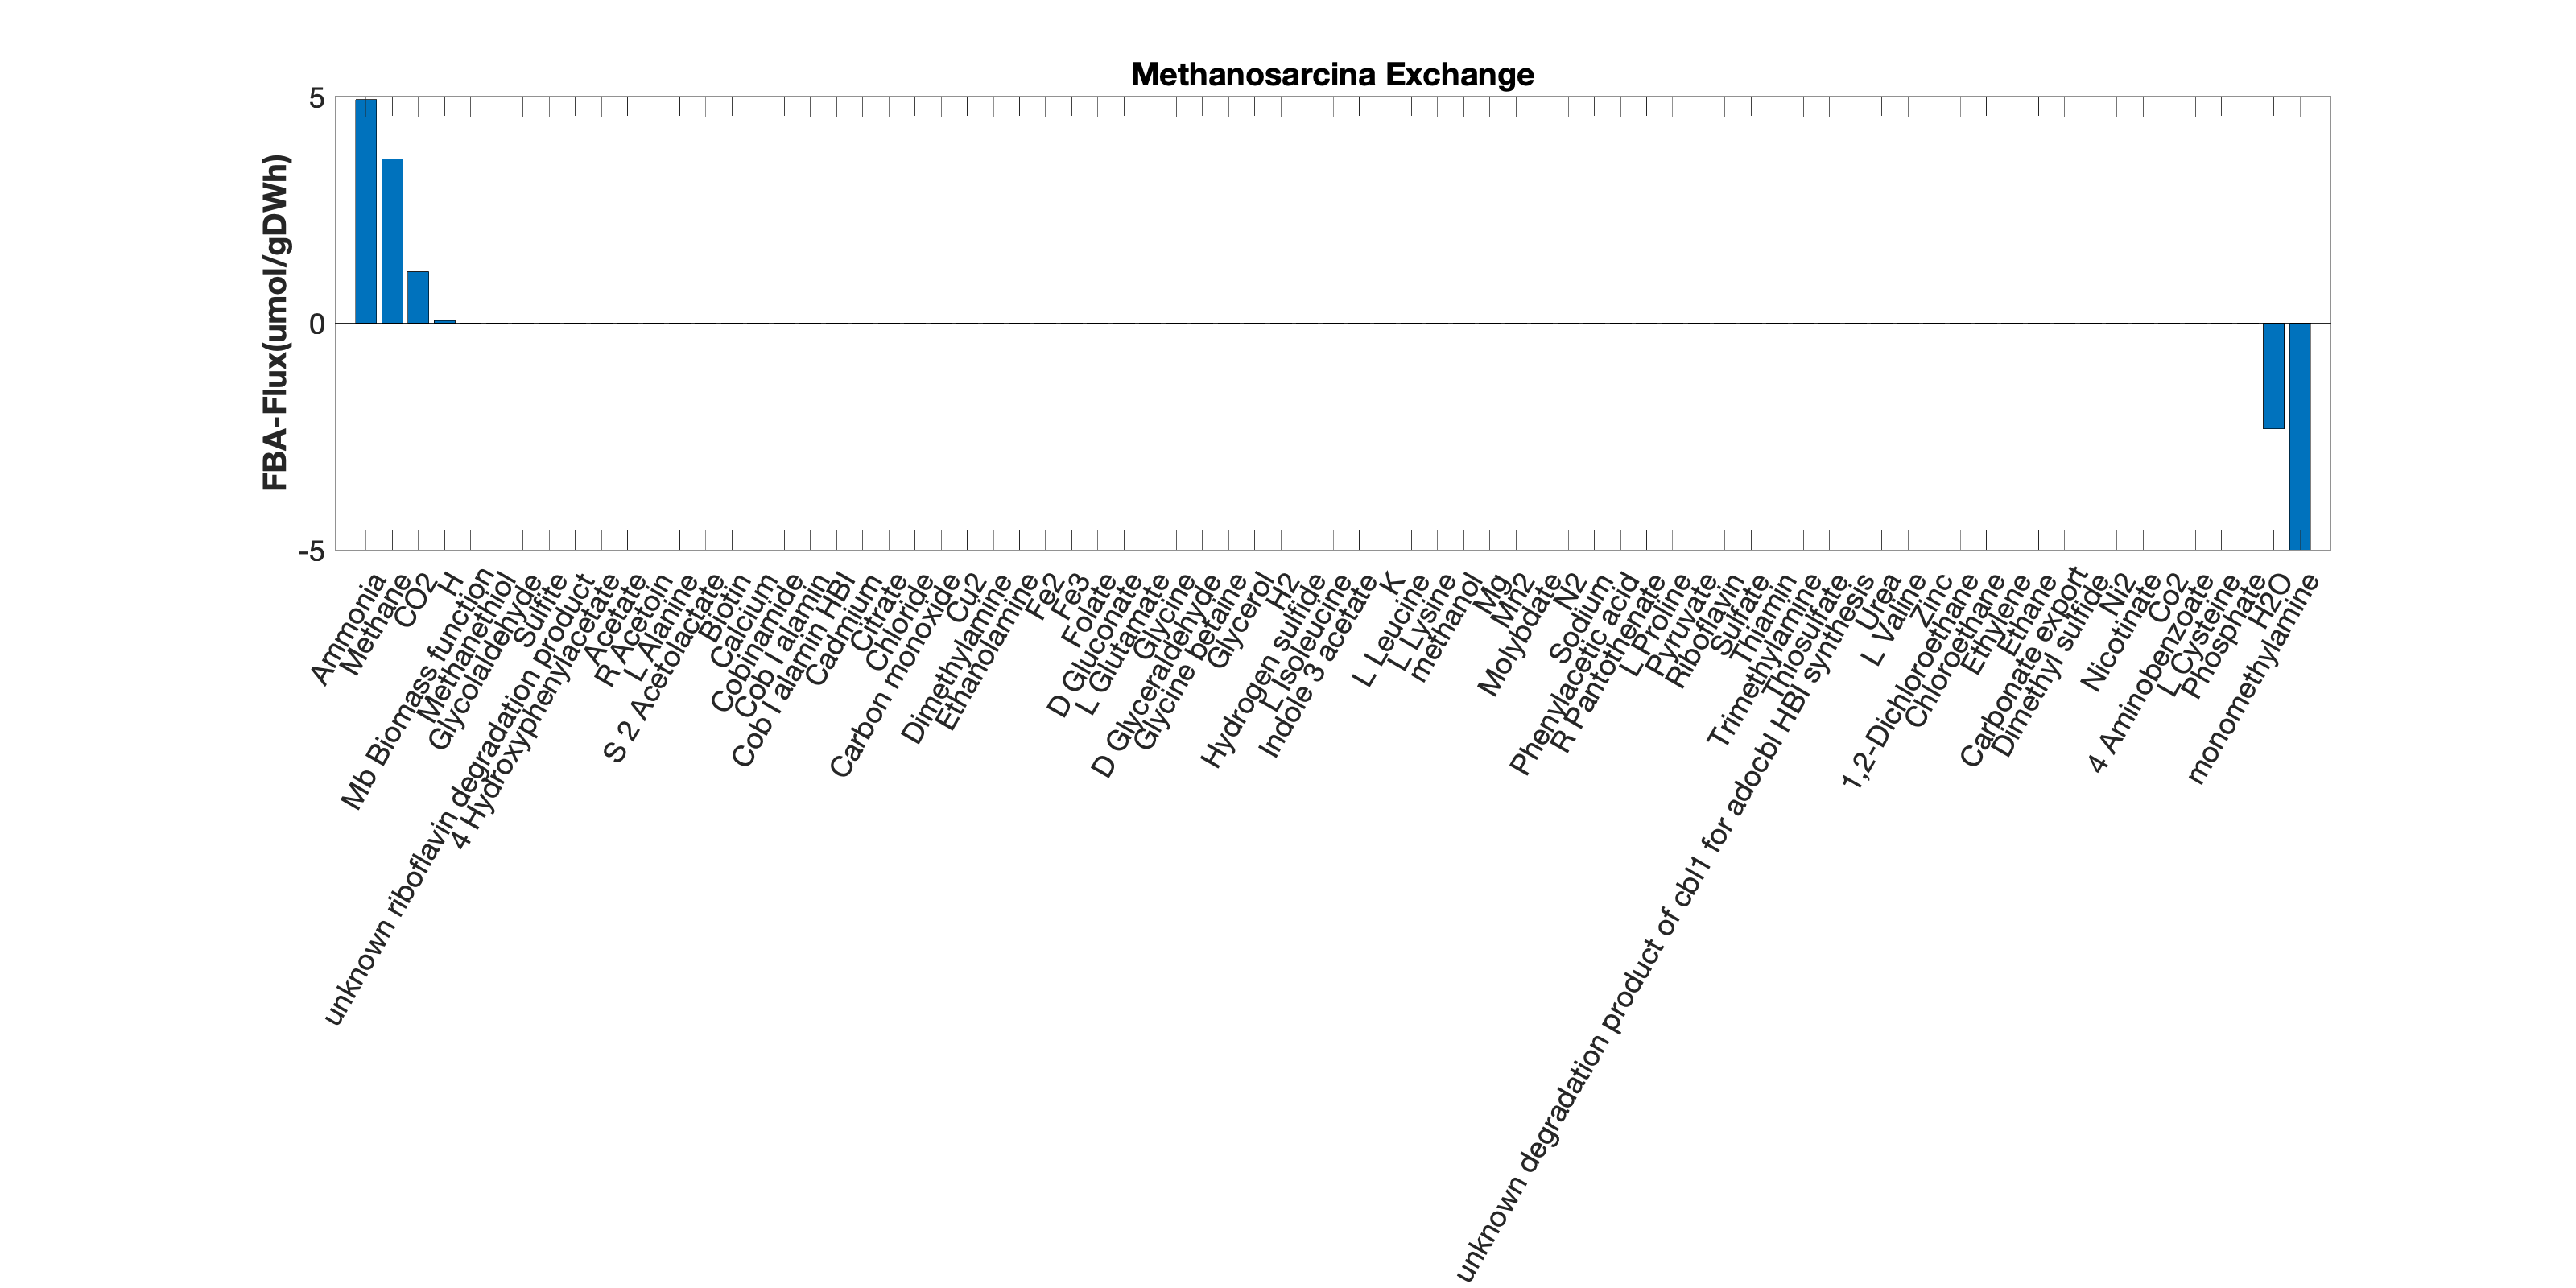

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"LPAREN e RPAREN");
c = erase(c,"exchange");

% c(find(contains(c,'_')))='-';

sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',18)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',14,'FontWeight','bold')
title(['Methanosarcina ',char(exchangeSubSystems)],'FontSize',18);

**Dimethylamine**

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_dma(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
BIOMASS(5) = FBAsolution.v(model.c~=0)

BIOMASS =     0.0173    0.0663    0.0130    0.0060    0.0361


methaneProduction(5) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}))

methaneProduction =     3.4043    9.9220    4.7401    3.6294    6.7757


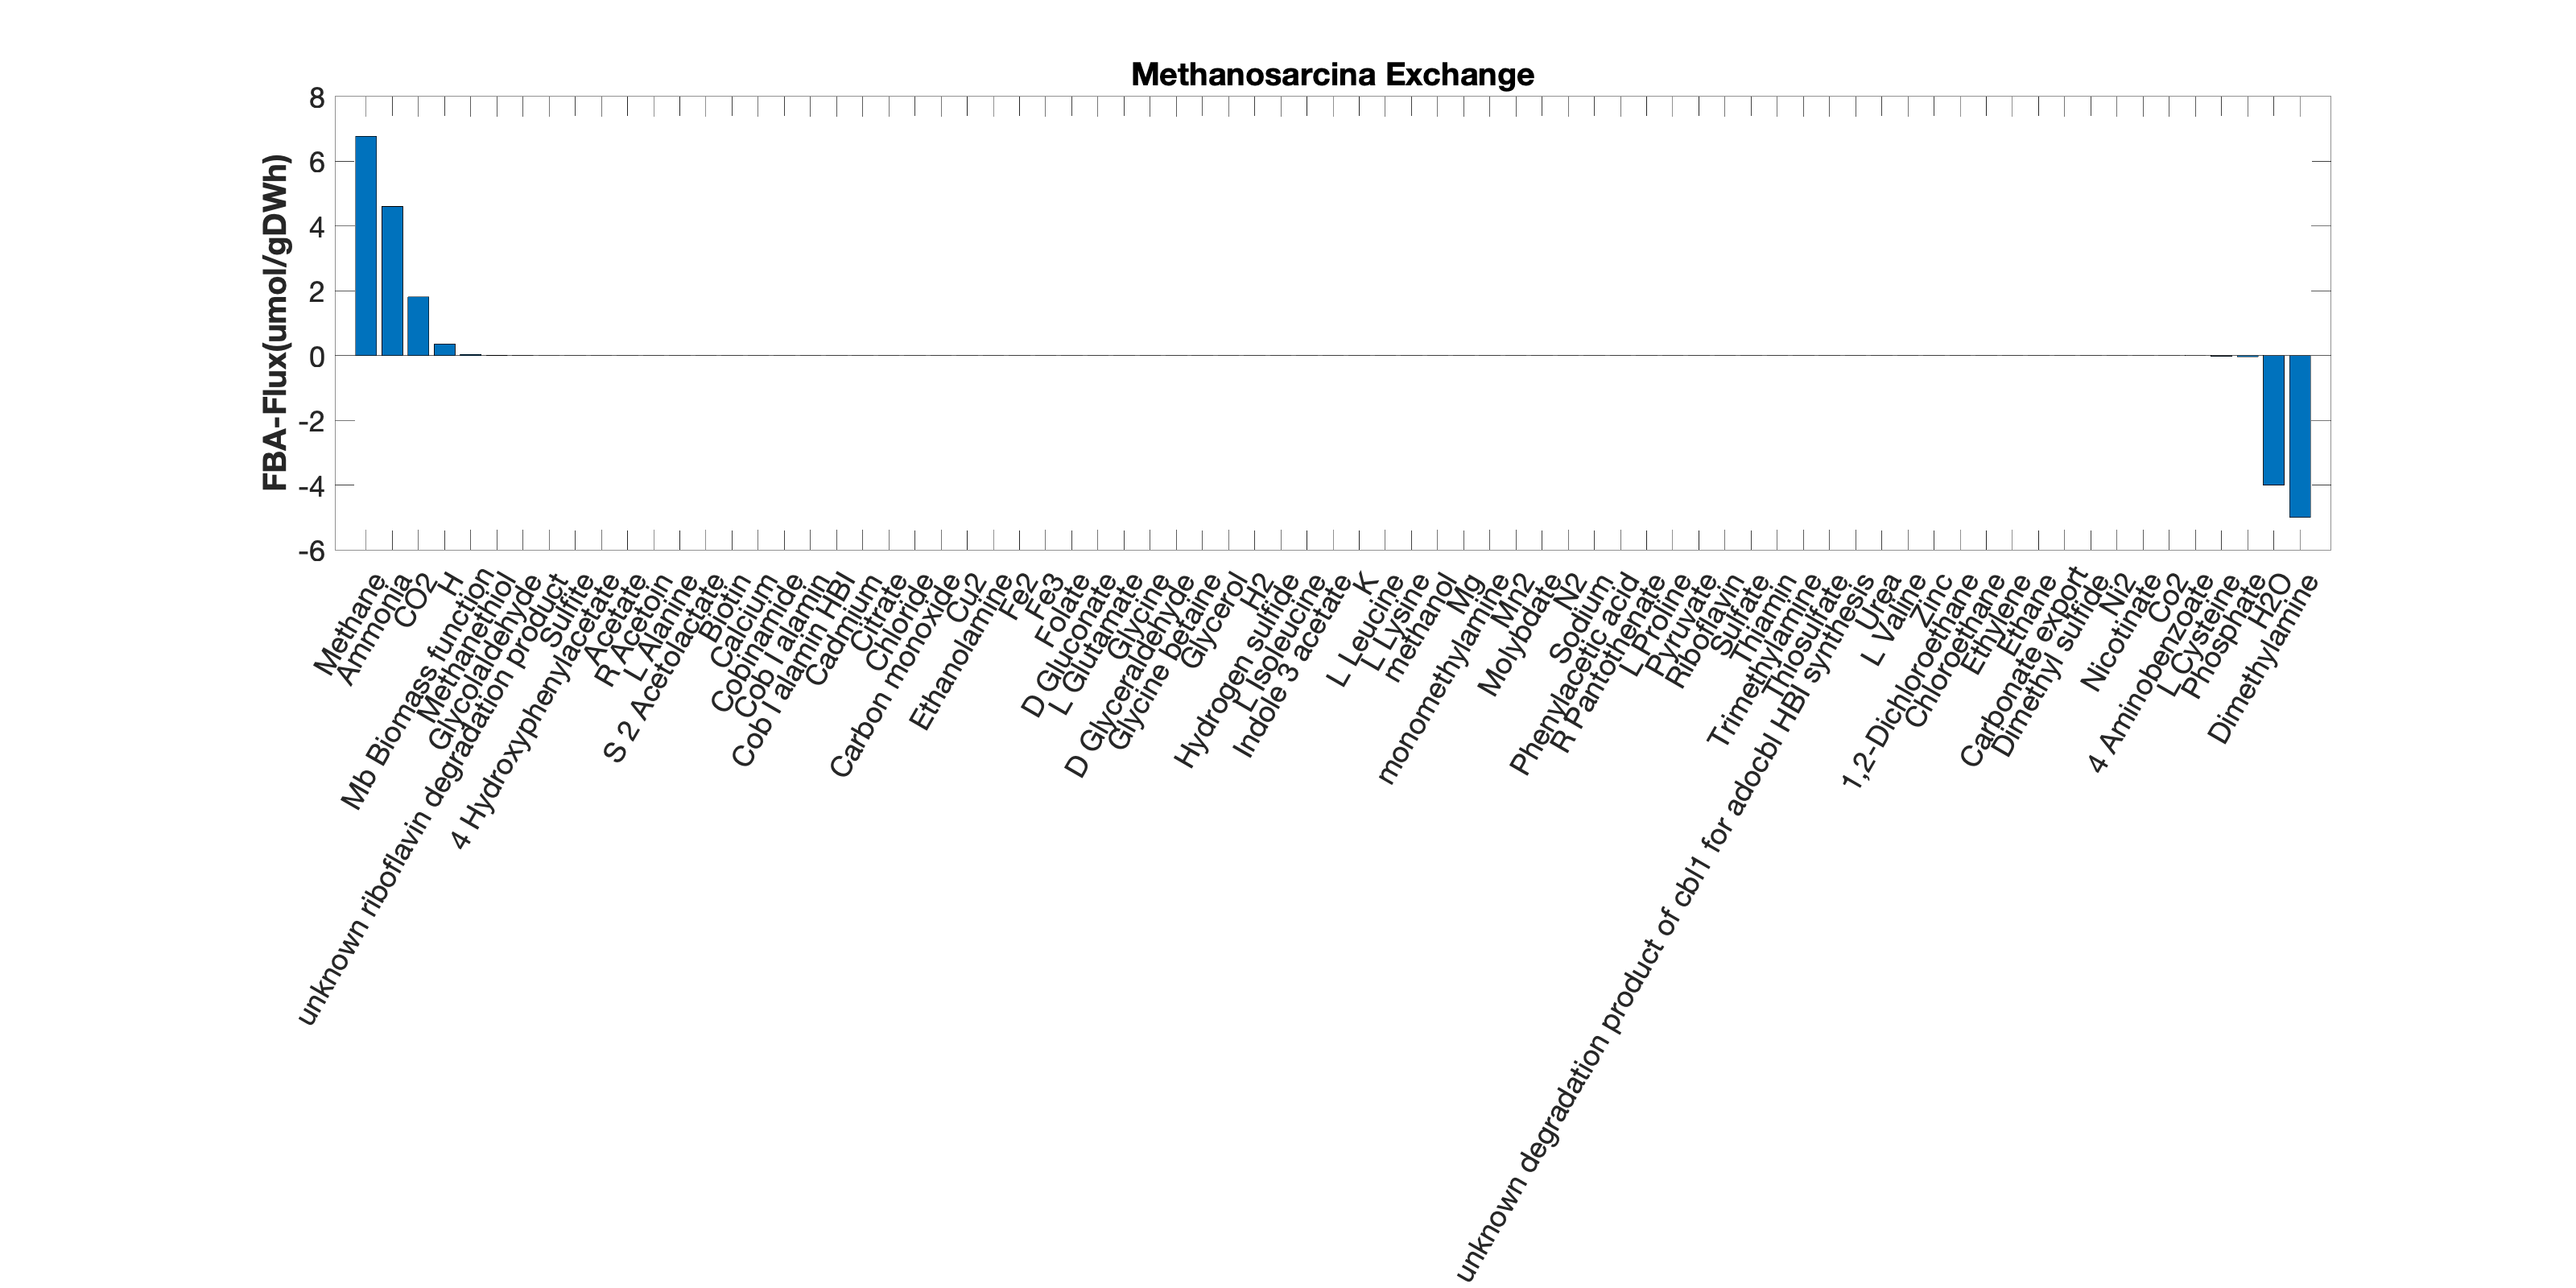

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"LPAREN e RPAREN");
c = erase(c,"exchange");

% c(find(contains(c,'_')))='-';

sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',18)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',14,'FontWeight','bold')
title(['Methanosarcina ',char(exchangeSubSystems)],'FontSize',18);

**Carbon monoxide (CO)** 

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_co(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
BIOMASS(6) = FBAsolution.v(model.c~=0)

BIOMASS =     0.0173    0.0663    0.0130    0.0060    0.0361    0.0107


methaneProduction(6) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}))

methaneProduction =     3.4043    9.9220    4.7401    3.6294    6.7757    1.0365


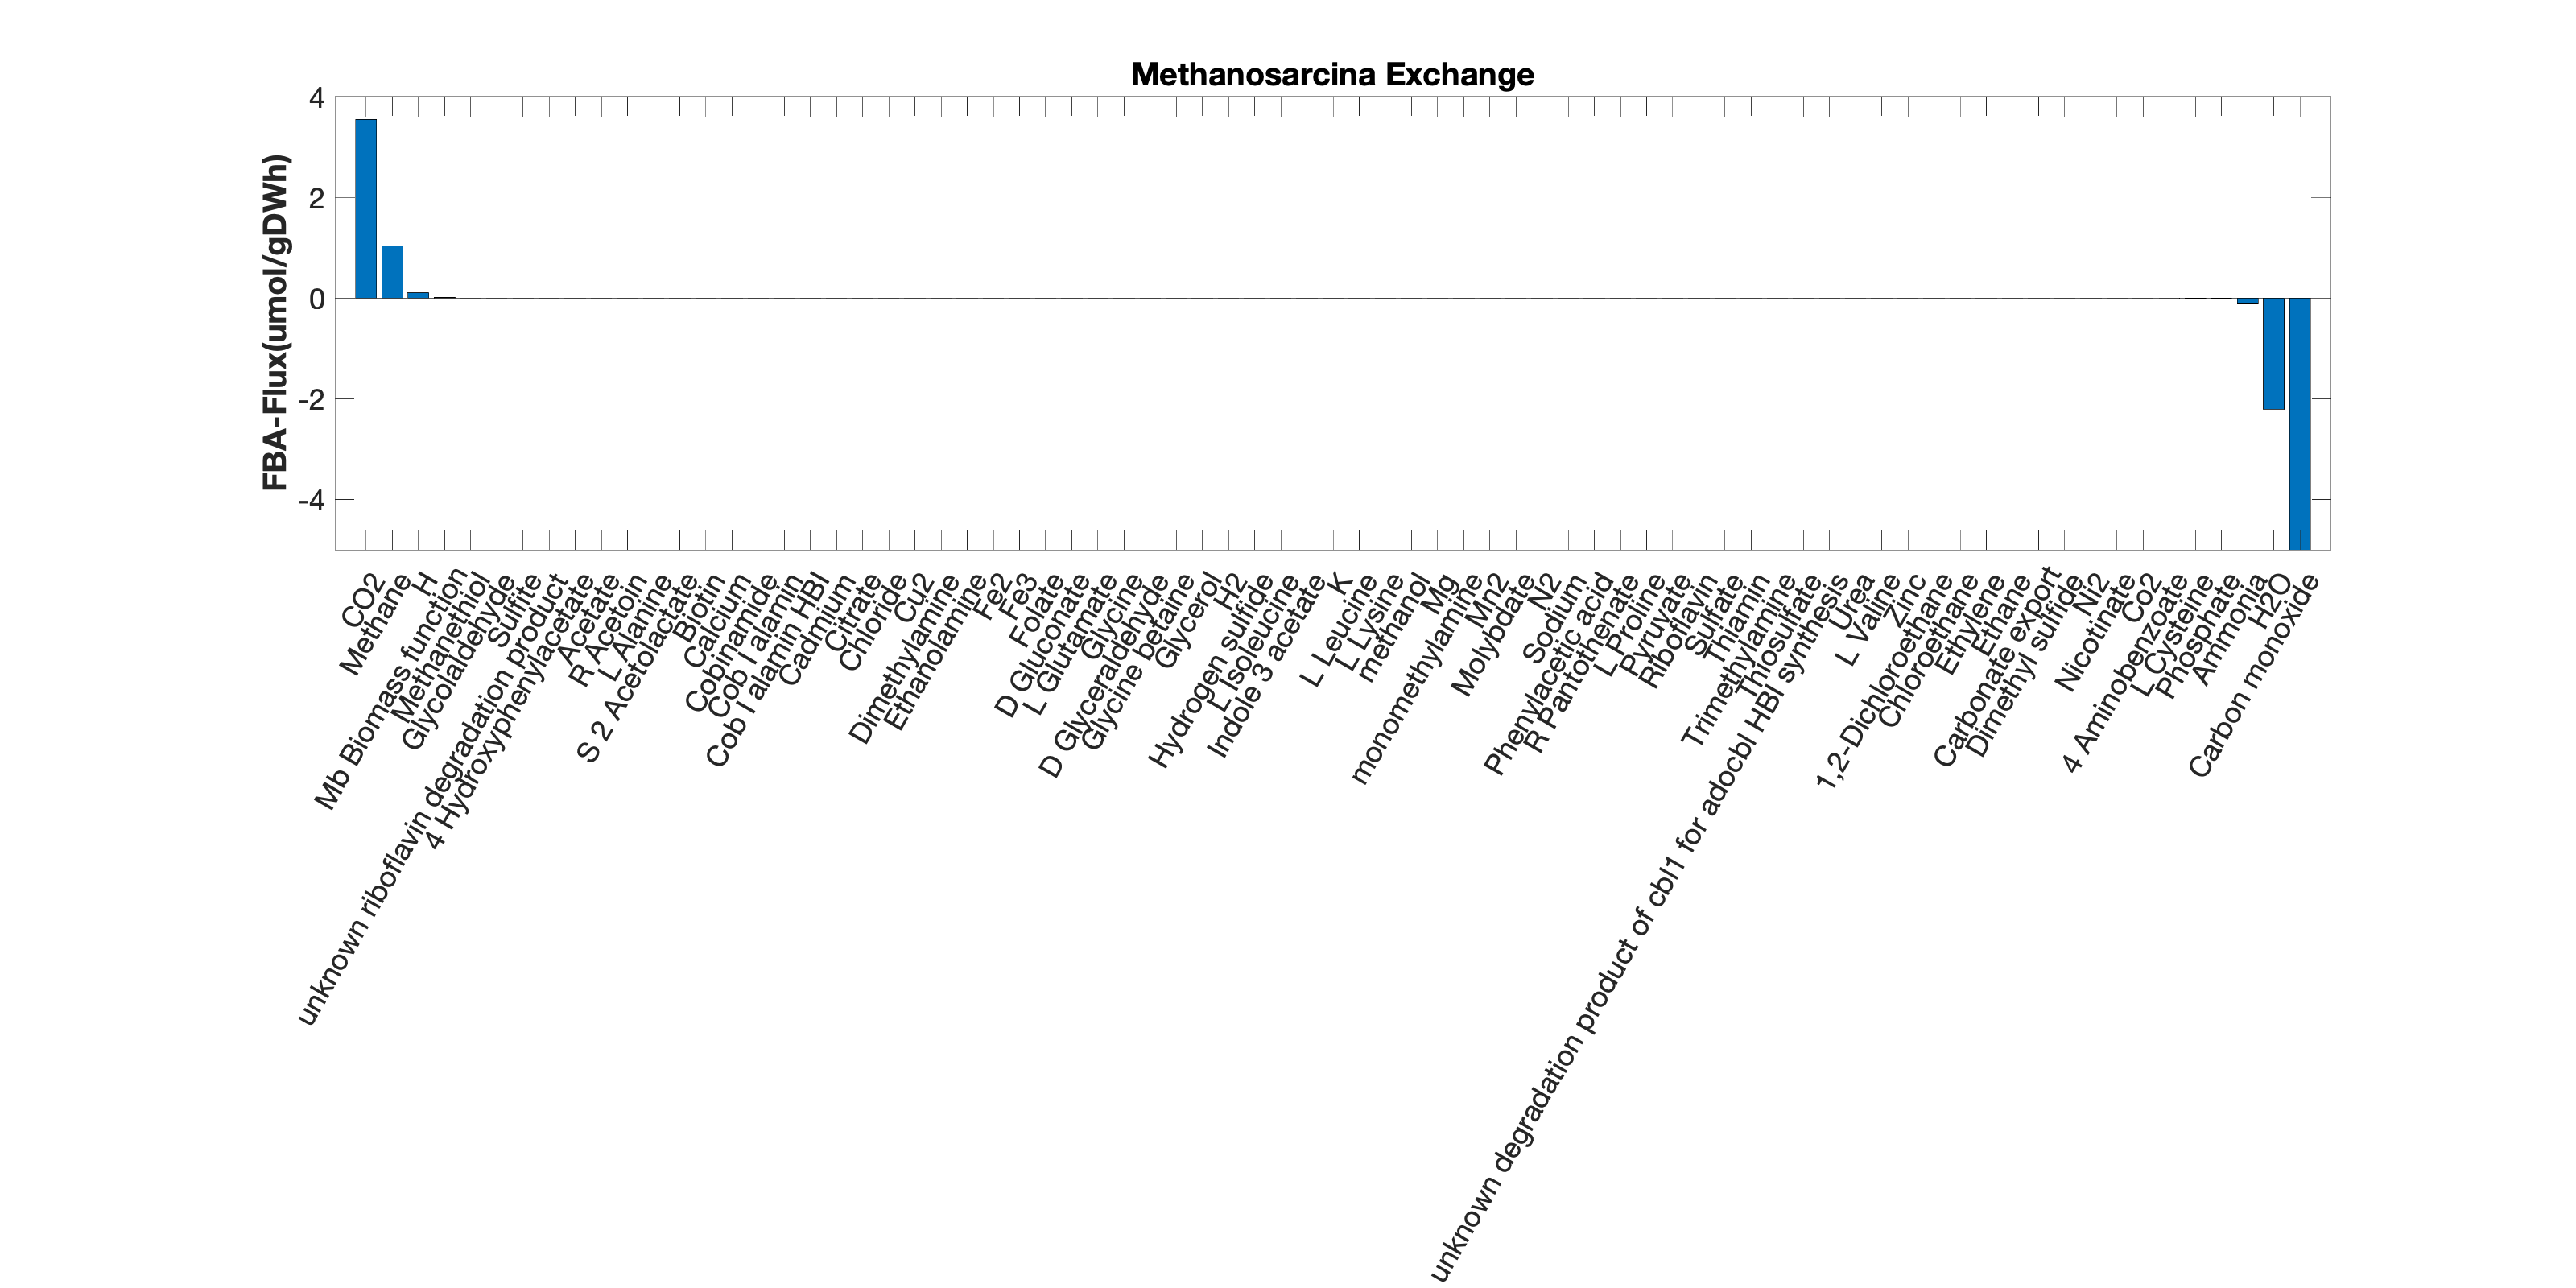

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"LPAREN e RPAREN");
c = erase(c,"exchange");

% c(find(contains(c,'_')))='-';

sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',18)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',14,'FontWeight','bold')
title(['Methanosarcina ',char(exchangeSubSystems)],'FontSize',18);

**CO2 (carbon dioxide)** 

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_meoh(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_co2(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
if FBAsolution.stat ==1
BIOMASS(7) = FBAsolution.v(model.c~=0)
methaneProduction(7) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'})) 
else
   BIOMASS(7) = 0
   methaneProduction(7) = 0  
end

BIOMASS =     0.0173    0.0663    0.0130    0.0060    0.0361    0.0107    0.0208


methaneProduction =     3.4043    9.9220    4.7401    3.6294    6.7757    1.0365    5.9840


**Methanethiol (CH4S)**

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_ch4s(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
if FBAsolution.stat ==1
BIOMASS(8) = FBAsolution.v(model.c~=0)
methaneProduction(8) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'})) 
else
   BIOMASS(8) = 0
   methaneProduction(8) = 0  
end

BIOMASS =     0.0173    0.0663    0.0130    0.0060    0.0361    0.0107    0.0208         0


methaneProduction =     3.4043    9.9220    4.7401    3.6294    6.7757    1.0365    5.9840         0


**Ethanolamine**

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


%remove methanol from environment, by setting its lower bound to zero
model.lb(findRxnIDs(model,{'EX_ac(e)'}))= 0;
model.lb(findRxnIDs(model,{'EX_etha(e)'}))= -5;

FBAsolution = optimizeCbModel(model);
if FBAsolution.stat ==1
BIOMASS(9) = FBAsolution.v(model.c~=0)
methaneProduction(9) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'})) 
else
   BIOMASS(9) = 0
   methaneProduction(9) = 0  
end

BIOMASS =     0.0173    0.0663    0.0130    0.0060    0.0361    0.0107    0.0208         0         0


methaneProduction =     3.4043    9.9220    4.7401    3.6294    6.7757    1.0365    5.9840         0         0


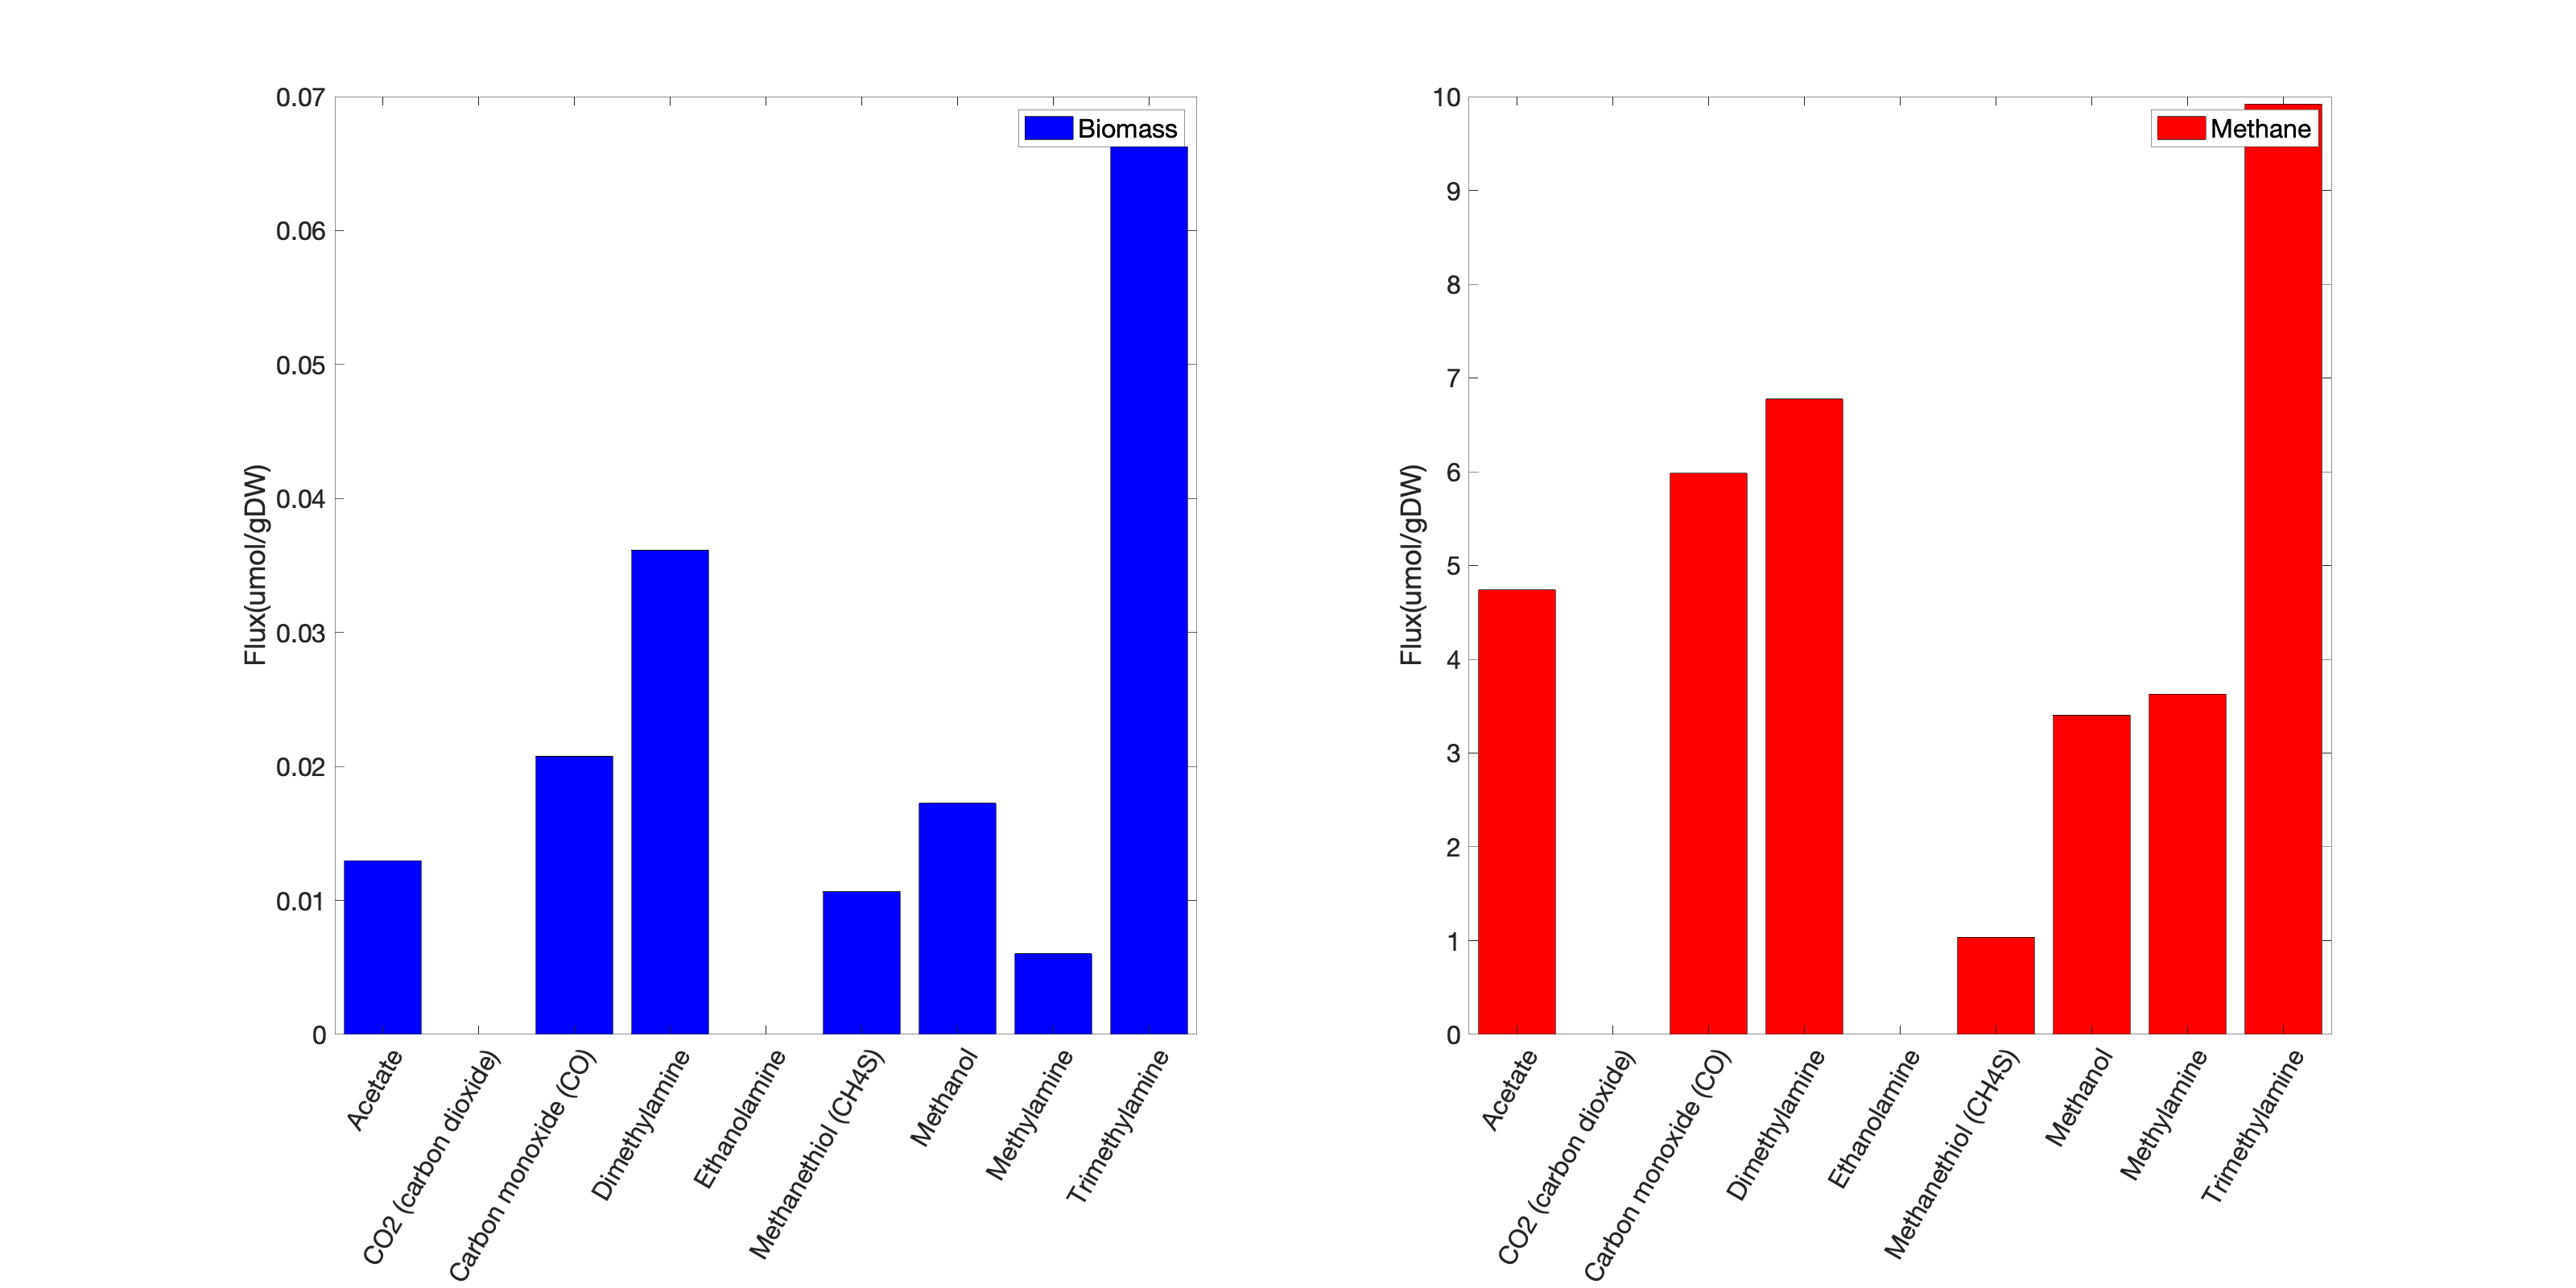

 figure('Renderer', 'painters', 'Position', [10 10 1600 800])
subplot(1,2,1)
x= {
'Methanol'
'Trimethylamine'
'Acetate'
'Methylamine' 
'Dimethylamine'
'Methanethiol (CH4S)'
'Carbon monoxide (CO)'
'CO2 (carbon dioxide)'
'Ethanolamine'};
y= [BIOMASS', methaneProduction'];
bar (categorical(x), y(:,1),'blue')
legend('Biomass', 'FontSize',16)
ylabel('Flux(umol/gDW)', 'FontSize',16);
set(gca,'XTickLabelRotation',60, 'FontSize',16)
subplot(1,2,2)
bar (categorical(x), y(:,2), 'red')
legend("Methane",'FontSize',16)
ylabel('Flux(umol/gDW)', 'FontSize',16);
set(gca,'XTickLabelRotation',60, 'FontSize',16)

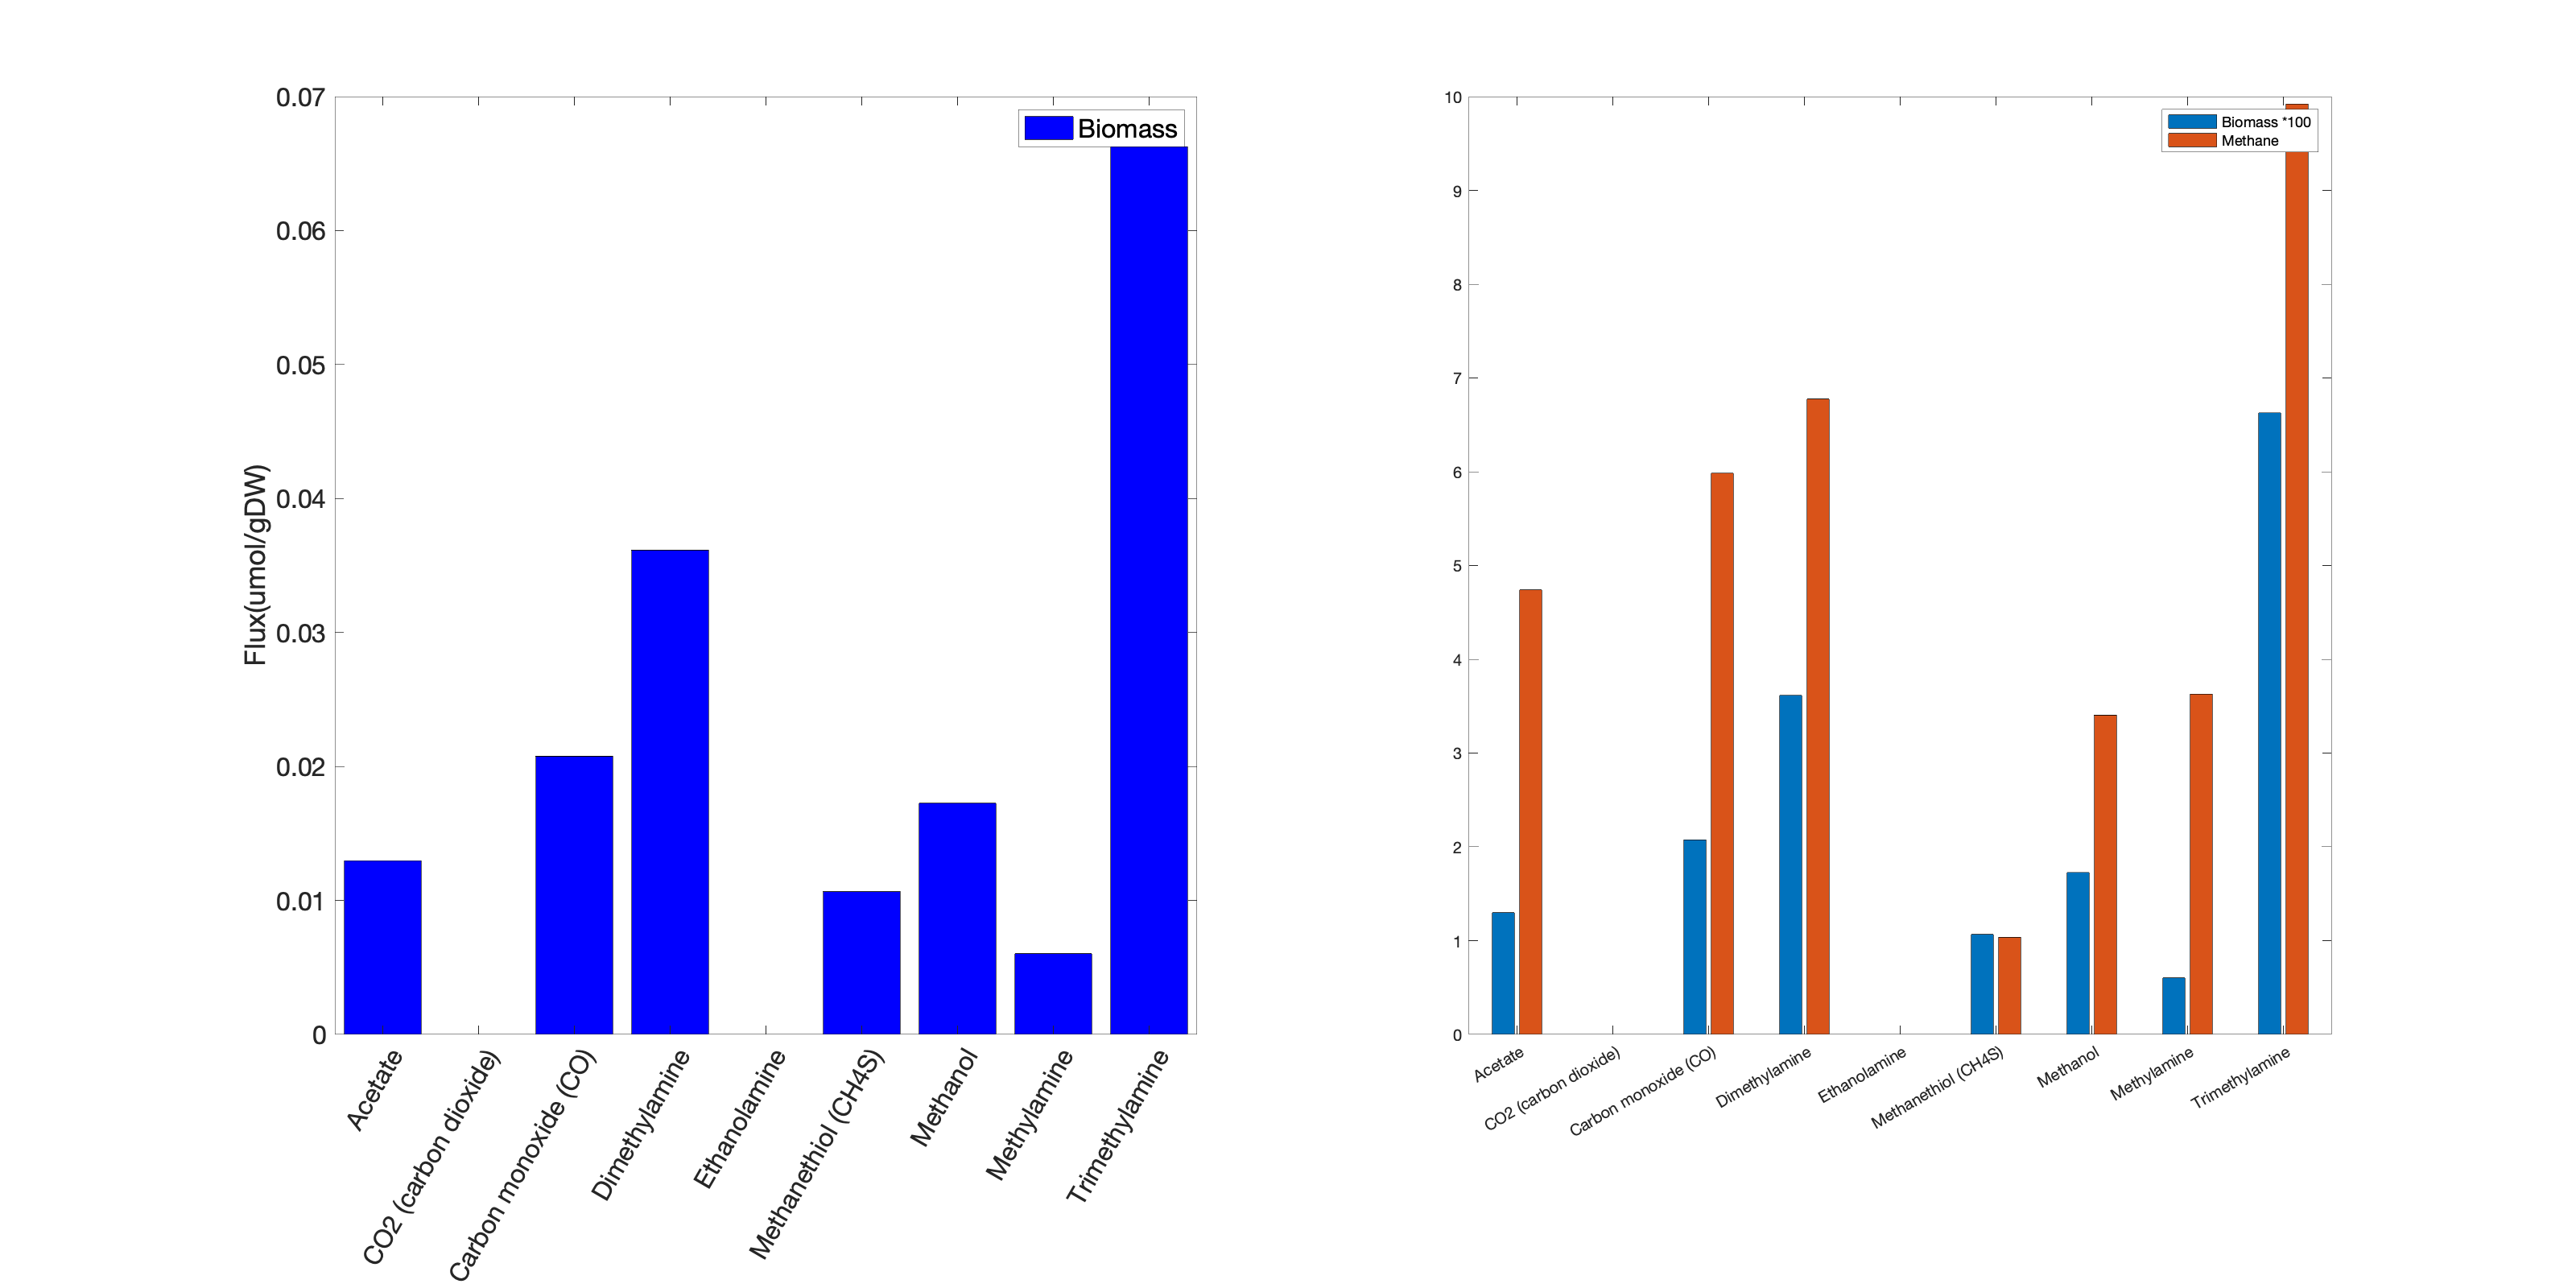

bar (categorical(x), [y(:,1)*100,y(:,2)])
legend('Biomass *100', "Methane")

clc
clearvars -except BIOMASS methaneProduction
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.



% Define different carbon sources
carbon_sources = {'EX_meoh(e)', 'EX_tma(e)', 'EX_ac(e)', 'EX_mma(e)', 'EX_dma(e)', 'EX_ch4s(e)', 'EX_co(e)', 'EX_co2(e)', 'EX_etha(e)'};

% Preallocate results arrays (adjust size according to the number of carbon sources)
BIOMASS = zeros(1, length(carbon_sources));
methaneProduction = zeros(1, length(carbon_sources));

% Loop over different carbon sources
for i = 1:length(carbon_sources)
    % Load the model fresh each time to reset any changes
    model = readCbModel('mba_model.xml');
    
%     load('Methanosarcina.mat')
    
    % Remove methanol from environment, by setting its lower bound to zero
    model.lb(findRxnIDs(model,{'EX_ac(e)'})) = 0;
    
    % Set the lower bound of the carbon source to -5.1
    model.lb(findRxnIDs(model, carbon_sources{i})) = -5;
    
    % Run the optimization
    FBAsolution = optimizeCbModel(model);
    
    % Check if the optimization was successful
    if FBAsolution.stat == 1
        BIOMASS(i) = FBAsolution.v(findRxnIDs(model,{'Mb_biomass_65'}));  % Store biomass production
        methaneProduction(i) = FBAsolution.v(findRxnIDs(model,{'EX_ch4(e)'}));  % Store methane production
    else
        BIOMASS(i) = 0;
        methaneProduction(i) = 0;
    end
end

One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.
One subSystem per reaction, so each model.subSystems{x} is a character array.



% Display the results
disp('BIOMASS:');

BIOMASS:


disp(BIOMASS);

    0.0173    0.0663    0.0130    0.0060    0.0361         0    0.0107         0         0



disp('Methane Production:');

Methane Production:


disp(methaneProduction);

    3.4043    9.9220    4.7401    3.6294    6.7757         0    1.0365         0         0



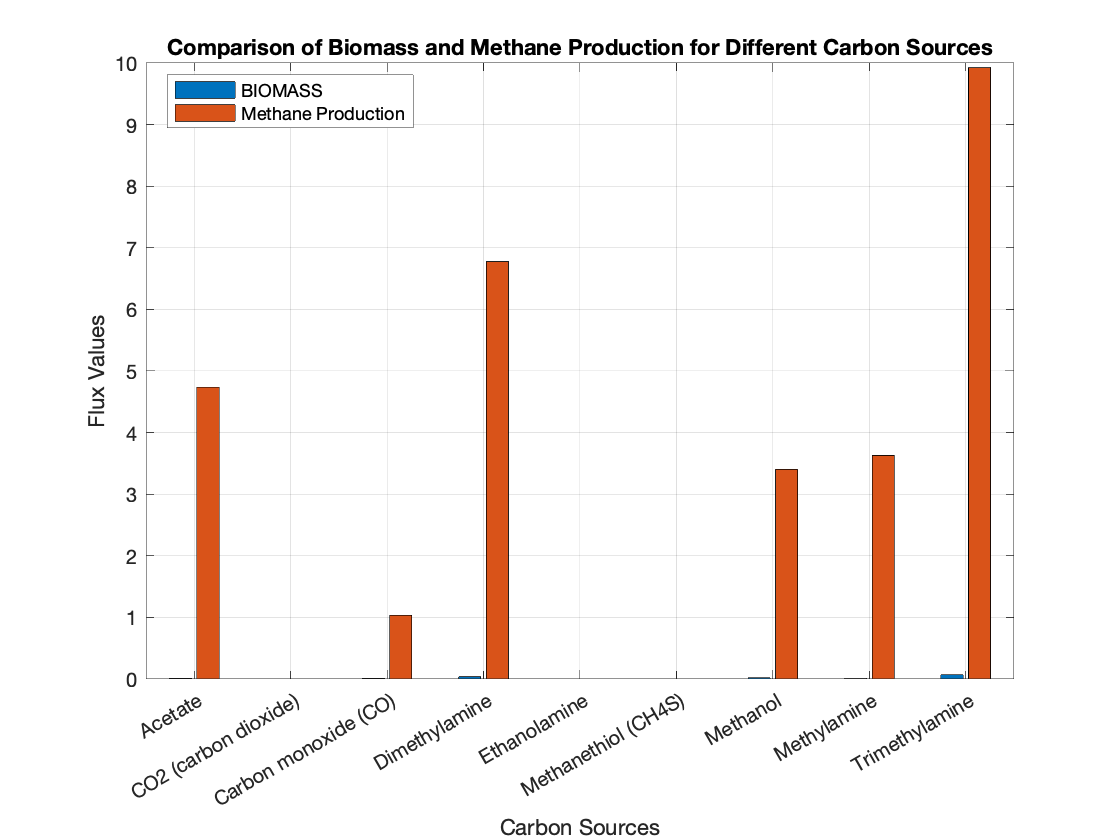


% Create bar chart to compare BIOMASS and methane production
figure;
x_labels = categorical({
    'Methanol', 'Trimethylamine', 'Acetate', 'Methylamine', 'Dimethylamine', ...
    'Methanethiol (CH4S)', 'Carbon monoxide (CO)', 'CO2 (carbon dioxide)', 'Ethanolamine'});
bar(x_labels, [BIOMASS' methaneProduction'], 'grouped')
xlabel('Carbon Sources')
ylabel('Flux Values')
legend({'BIOMASS', 'Methane Production'}, 'Location', 'Best')
title('Comparison of Biomass and Methane Production for Different Carbon Sources')
grid on

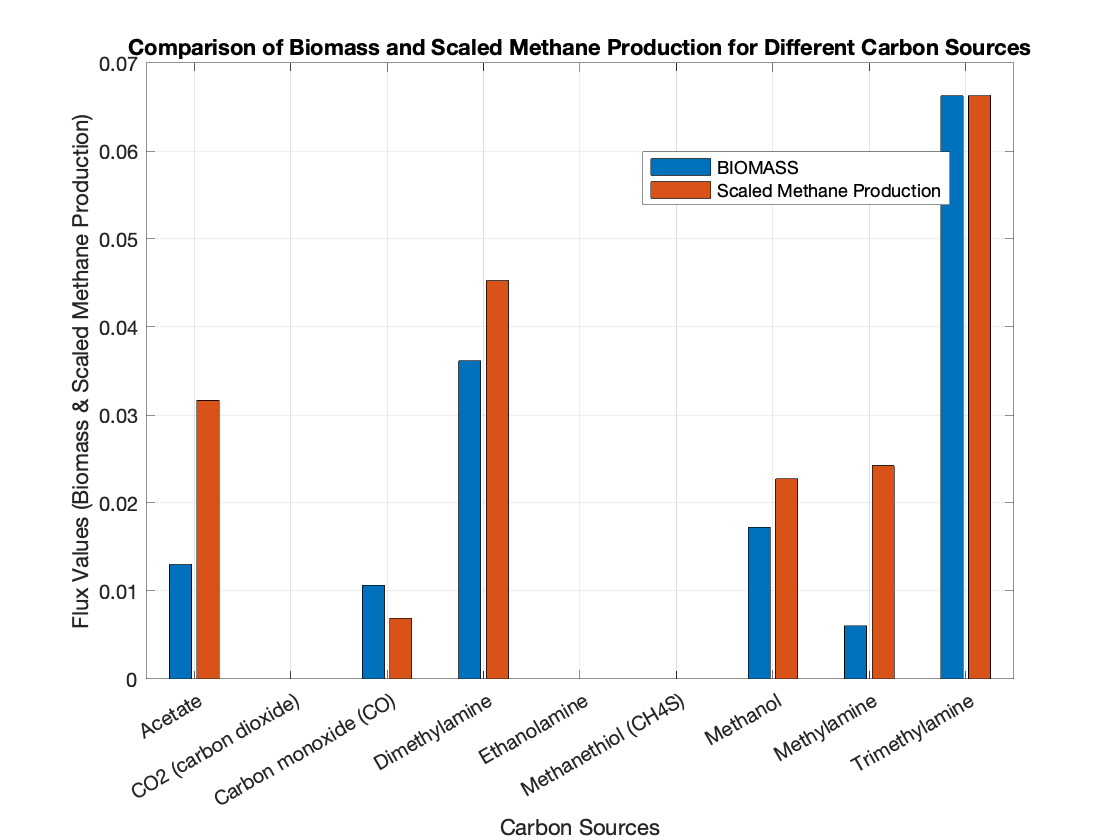

% Normalize or scale methane production so that it fits on the same scale
scaled_methaneProduction = methaneProduction * (max(BIOMASS) / max(methaneProduction));  % Scale methane to biomass range

% Create the bar chart with grouped bars
figure;
x_labels = categorical({
    'Methanol', 'Trimethylamine', 'Acetate', 'Methylamine', 'Dimethylamine', ...
    'Methanethiol (CH4S)', 'Carbon monoxide (CO)', 'CO2 (carbon dioxide)', 'Ethanolamine'});
bar(x_labels, [BIOMASS' scaled_methaneProduction'], 'grouped')  % Plot both BIOMASS and scaled methane

% Customize labels
xlabel('Carbon Sources')
ylabel('Flux Values (Biomass & Scaled Methane Production)')
legend({'BIOMASS', 'Scaled Methane Production'}, 'Location', 'Best')
title('Comparison of Biomass and Scaled Methane Production for Different Carbon Sources')
grid on

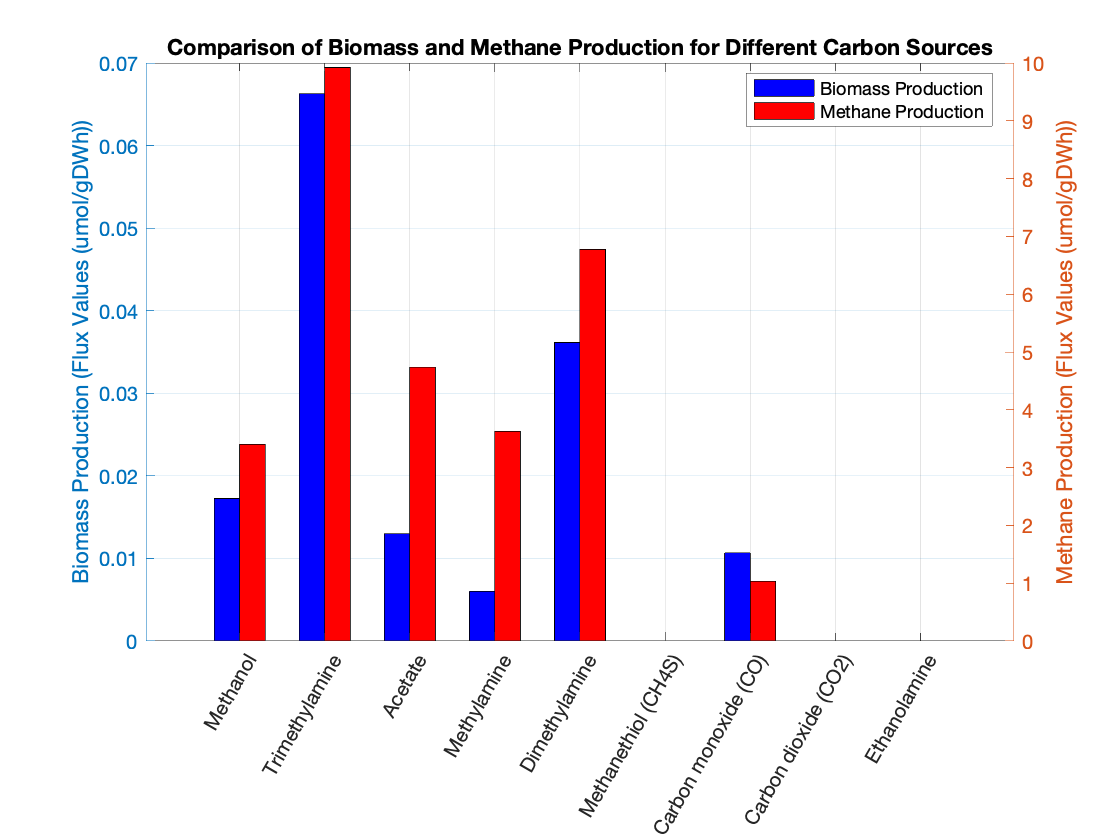

figure;

x = 1:length(BIOMASS);  % Create a numeric x-axis for the categories

% Create bars for biomass on the left axis
yyaxis left
b1 = bar(x - 0.15, BIOMASS, 0.3, 'FaceColor', 'b');  % Shift biomass bars slightly to the left
ylabel('Biomass Production (Flux Values (umol/gDWh))')

% Hold the figure to overlay the second bar
hold on

% Create bars for methane production on the right axis
yyaxis right
b2 = bar(x + 0.15, methaneProduction, 0.3, 'FaceColor', 'r');  % Shift methane bars slightly to the right
ylabel('Methane Production (Flux Values (umol/gDWh))')

% Define x-tick labels as the carbon sources
x_labels = categorical({
    'Methanol', 'Trimethylamine', 'Acetate', 'Methylamine', 'Dimethylamine', ...
    'Methanethiol (CH4S)', 'Carbon monoxide (CO)', ' Carbon dioxide (CO2)', 'Ethanolamine'});

% Set the x-ticks and labels explicitly
set(gca, 'XTick', x, 'XTickLabel', x_labels);

% Rotate x-tick labels by 60 degrees
xtickangle(60);  % Rotate the x-tick labels to 60 degrees

% Add legend and title
legend({'Biomass Production', 'Methane Production'}, 'Location', 'Best')
title('Comparison of Biomass and Methane Production for Different Carbon Sources')
grid on